## Histogram Count Probabilities

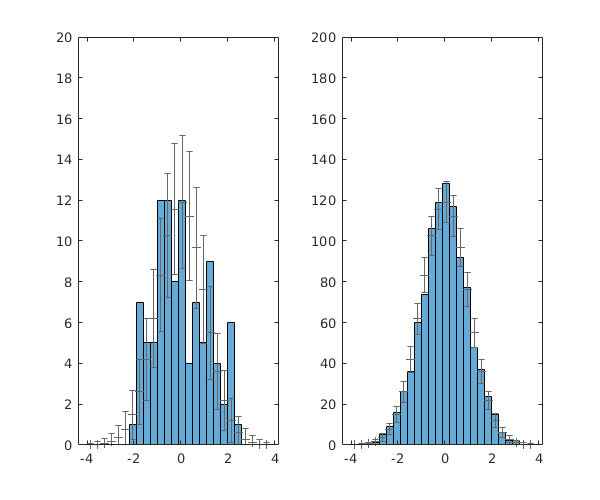

figure;
hold on;

N = 10 .^ [2, 3];
edges = -4:0.3:4;
centers = (edges(1:end-1) + edges(2:end))/2;

for i = 1:length(N)
    
    cdf = normcdf(edges);
    bin_probabilities = cdf(2:end) - cdf(1:end-1);
    mean = N(i) * bin_probabilities;
    std_dev = sqrt(mean .* (1 - bin_probabilities));
    
    subplot(1,length(N),i);
    
    samples = randn(N(i), 1);
    histogram(samples, edges);
    hold on;
    ylim([0, N(i)/5]);
    errorbar(centers, mean, std_dev, '+', 'color', 0.4 * ones(1,3), 'capsize', 4);
end

## Effect if p_j on count mean and variance.

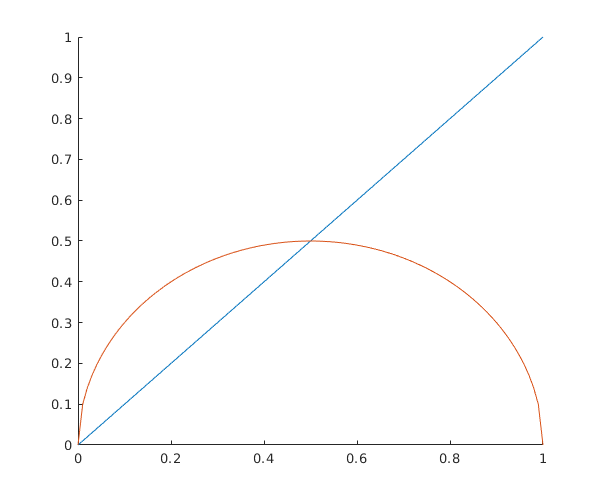

figure;
hold on;

p_j = linspace(0, 1, 100);
mean = p_j;
sd = sqrt(p_j .* (1-p_j));
plot(p_j, mean);
plot(p_j, sd);

## Effect of bin count - on middle bin

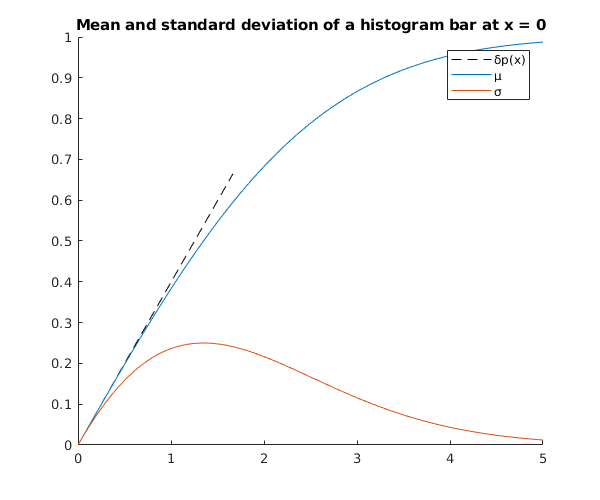

bin_position = 0;
bin_widths = linspace(0, 2.5 * (2 + bin_position), 100);
N = 1000;


means = zeros(size(bin_widths));
var = zeros(size(bin_widths));

for i = 1:length(bin_widths)
    edges = bin_position + bin_widths(i) * 0.5 * [-1 1];
    
    cdf = normcdf(edges);
    bin_probability = cdf(2) - cdf(1);
    means(i) = bin_probability;
    var(i) = means(i) * (1 - bin_probability);
    
    
    samples = randn(N, 1);
    [counts] = histcounts(samples, edges);
    
end

figure;
hold on;

a = max(0.5, bin_widths(end) / 3);

plot([0 a], [0 normpdf(bin_position) * a], '--k');
plot(bin_widths, means);
plot(bin_widths, var);

title(sprintf('Mean and standard deviation of a histogram bar at x = %g', bin_position));
legend(["δp(x)"; "μ"; "σ"]);

## Y = max(sin(X), Y_max)

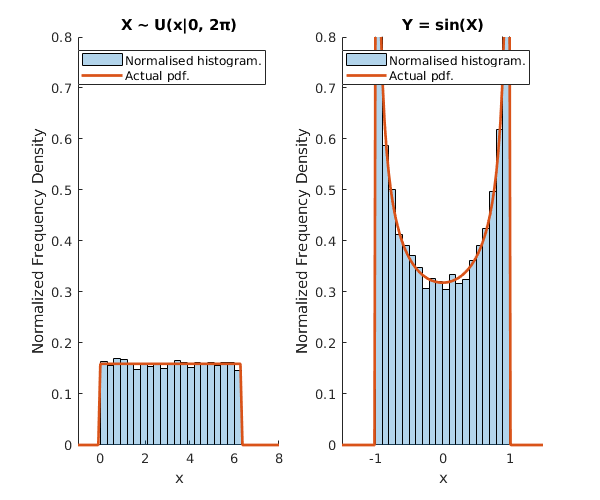

global t graph_max;
N = 10000;

Y_max = 1;

x = 2 * pi * rand(1, N);
y = min(sin(x), Y_max);

delta = @(x) 1e8 * (abs(x) < 1e-1);

graph_max = 0.8;
f_x = @(x) (x >= 0 & x <= 2 * pi) / (2*pi);
f_y = @(y) (y >= -1 & y <  Y_max) ./ (pi  .* sqrt(1 - y.^2));

figure;

subplot(1, 2, 1);
t = linspace(-1, 8, 100);
plot_histogram(x, f_x);
title('X ~ U(x|0, 2π)');

subplot(1, 2, 2);
t = linspace(-1.5, 1.5, 100);
plot_histogram(y, f_y);
title('Y = sin(X)');

## Exponential Distribution via Inverse CDF

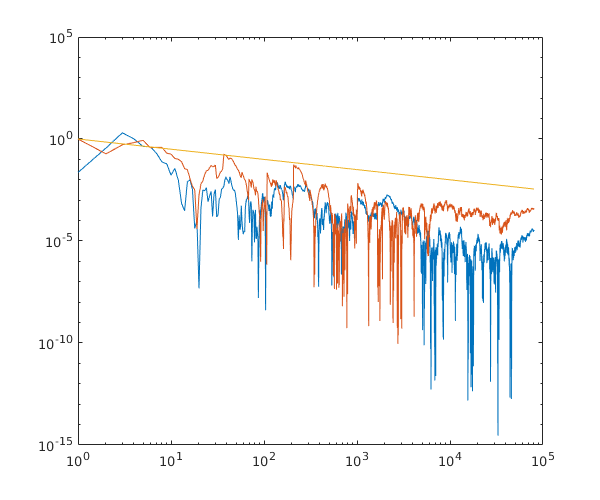

N = 80000;
lambda = 1;

mean = 1 / lambda;
var = 1 / lambda ^ 2;

f_inv_y = @(x) log(1 ./ (1 - x)) / lambda;
x = rand(1, N);
y = f_inv_y(x);

n = 1:N;

monty_means = cumsum(y) ./ n;
monty_vars = cumsum(y.^2) ./ n - monty_means.^2;

mse = (monty_means - mean).^2;
vse = (monty_vars - var).^2;

figure;
loglog(n, mse);
hold on;
plot(n, vse);
plot(n, var^2 ./ sqrt(n));

## Stable distribution

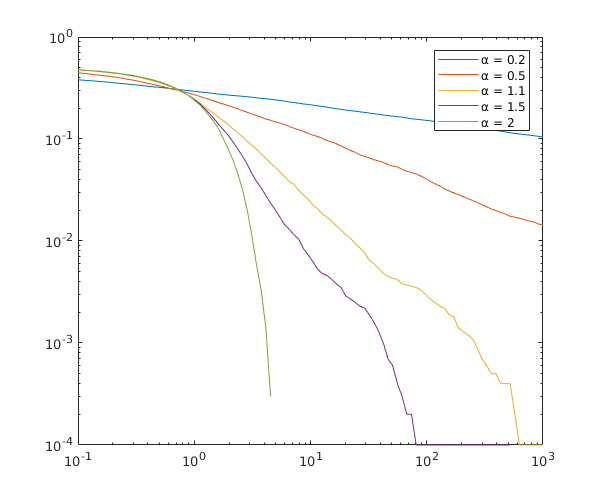

N = 100000;
uniform = (rand(N, 1) - 0.5) * pi;
expo = exprnd(1, [N, 1]);

repeats = 10;
beta = 0;
alpha = [0.2 0.5 1.1 1.5 2];
tail = logspace(-1, 3, 100);


A = zeros(length(alpha), length(tail), repeats);

for count = 1:repeats
    for i = 1:length(alpha)
       for j = 1:length(tail)
            x = generate_alpha_stable(alpha(i), beta, uniform, expo);

            A(i, j, count) = sum(x > tail(j)) / N;
       end
    end        
end

p_tail = sum(A, 3) / repeats;

figure;
loglog(tail, p_tail);
legend(arrayfun(@(alpha) sprintf("α = %g", alpha), alpha, 'UniformOutput', false))

function stairs2(x,y)
    A = zeros(2, length(x));
    B = zeros(2, length(x));
    for i=1:length(x)-1
        A(:,i) = [x(i) x(i+1)];
        B(:,i) = [y(i) y(i)];
    end
    plot(A,B,'Color','black');
end